## Functions, derivatives and knots

f = @(x) sin(x);                    % Function to interpolate
df = @(x) cos(x);                   % First derivative
d2f = @(x) -sin(x);                 % Second derivative

x = linspace(0, 2*pi, 20);      % Interpolation nodes
y = f(x);                       % Function values at nodes

% First and second derivatives
fpa = df(x(1));
fpb = df(x(end));
fppa = d2f(x(1));
fppb = d2f(x(end));

% Evaluation knots
xx = linspace(min(x), max(x), 1000);
true_y = f(xx);

## Generate splines

S_complete = spline_complete(x, y, fpa, fpb);
S_second   = spline_second_deriv(x, y, fppa, fppb);
S_natural  = spline_natural(x, y);
S_deboor   = spline_deboor(x, y);

## Evaluate splines

y_complete = S_complete(xx);
y_second   = S_second(xx);
y_natural  = S_natural(xx);
y_deboor   = S_deboor(xx);

## Comparison plots

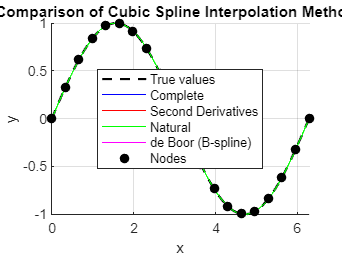

figure;
hold on;
plot(xx, true_y, 'k--', 'LineWidth', 1.5, 'DisplayName', 'True values');
plot(xx, y_complete, 'b', 'DisplayName', 'Complete');
plot(xx, y_second, 'r', 'DisplayName', 'Second Derivatives');
plot(xx, y_natural, 'g', 'DisplayName', 'Natural');
plot(xx, y_deboor, 'm', 'DisplayName', 'de Boor (B-spline)');
plot(x, y, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Nodes');

legend('Location', 'Best');
xlabel('x'); ylabel('y');
title('Comparison of Cubic Spline Interpolation Methods');
grid on; hold off;